loding data

clear

Path = {    'DeepLearningData/Normal/M',...
             'DeepLearningData/Normal/T'};
 imds = imageDatastore(Path,'IncludeSubfolders',true,'LabelSource','foldernames');
 

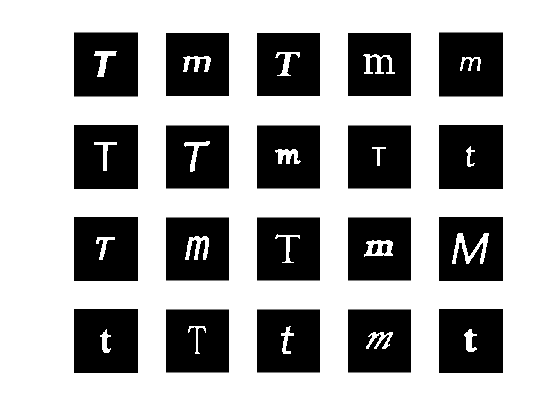

  figure;
        perm = randperm(length(imds.Files),20);
        for i = 1:20
            subplot(4,5,i);
            imshow(imds.Files{perm(i)});
        end

        labelCount = countEachLabel(imds)   

labelCount = 2×2 table
    Label    Count
    _____    _____

      M       600 
      T       600 


  numTrainFiles = 400;
  [imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');
  

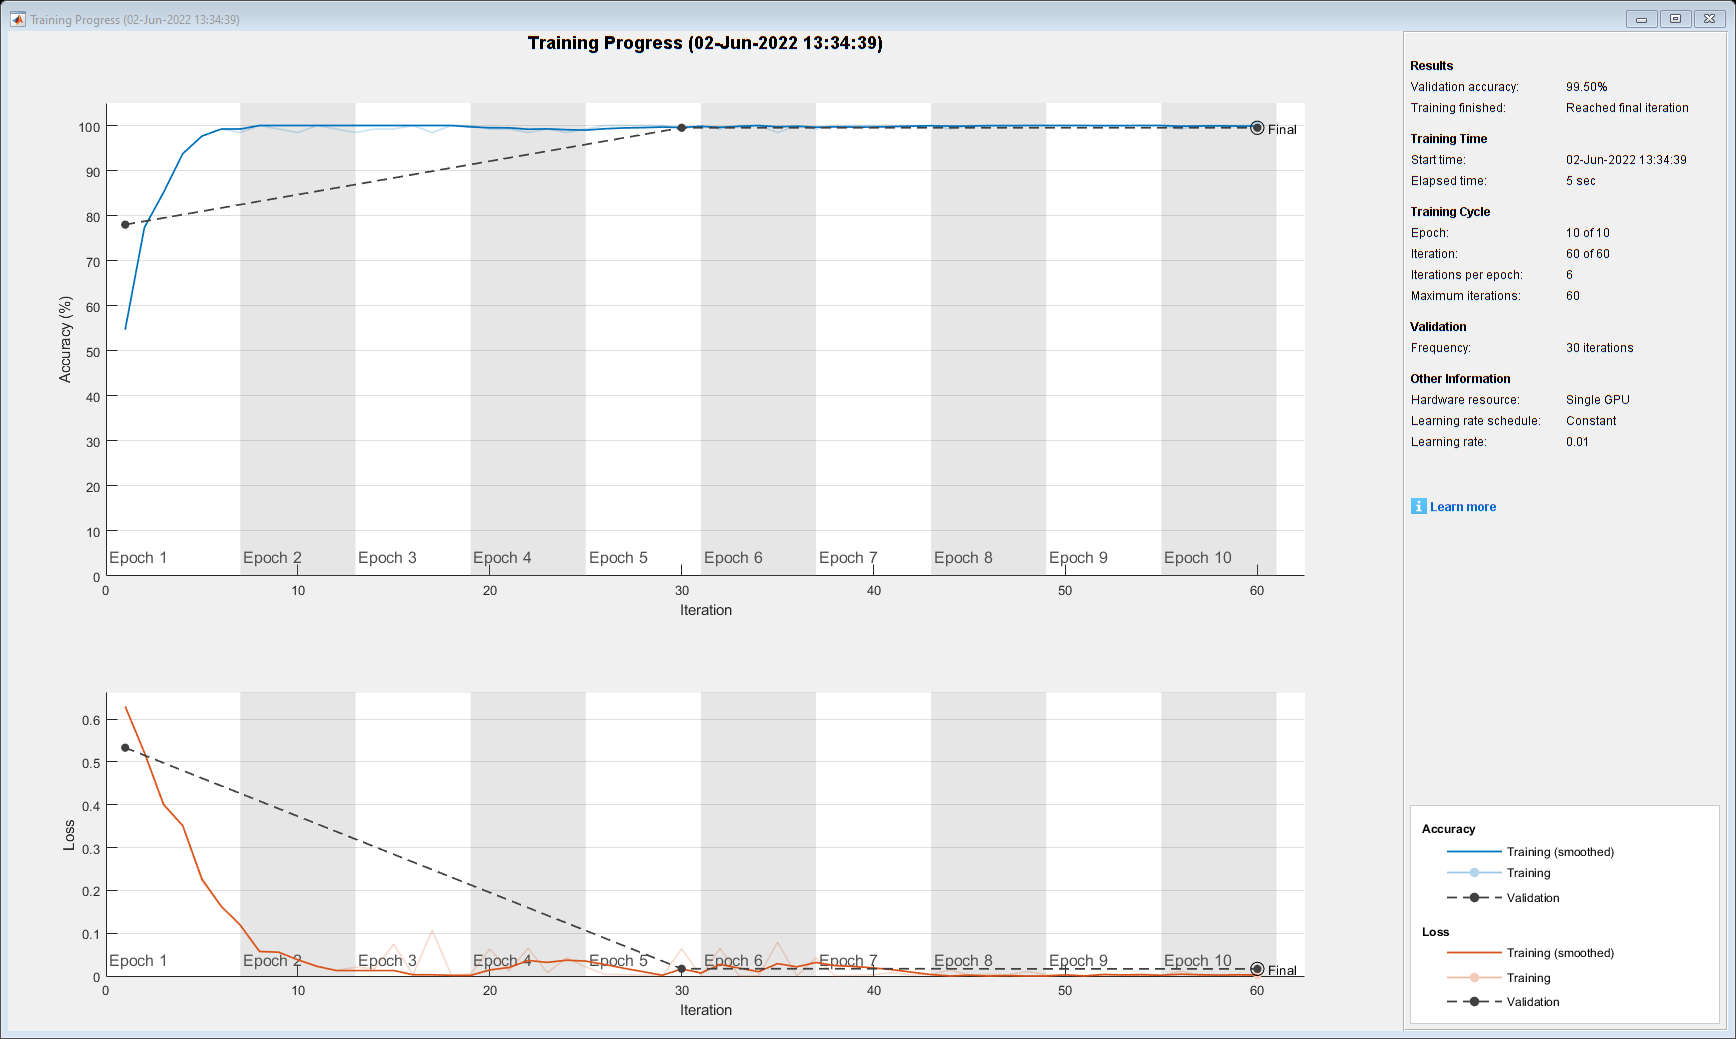

net =   SeriesNetwork with properties:

         Layers: [8×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


% imageInputLayer([150 150 1]) 
% 
% convolution2dLayer(3,8,'Padding','same')
% batchNormalizationLayer
% reluLayer
% maxPooling2dLayer(2,'Stride',2)


layers = [
imageInputLayer([150 150 1])
fullyConnectedLayer(10)
reluLayer
fullyConnectedLayer(10)
reluLayer
fullyConnectedLayer(2)
softmaxLayer
classificationLayer];

[net] = nettrainset(imdsTrain,imdsValidation,layers)

Path = { 'DeepLearningData/W2/M',...
'DeepLearningData/W2/T'};
imdsTest = imageDatastore(Path,'IncludeSubfolders',true,'LabelSource','foldernames');

[accuracy,~,~]=getaccontest(net,imdsTest)

accuracy = 0.9850